%{
Program to denoise images using low rank completion methods
Harsh Shah and Pranava Singhal 
%}

addpath '.\MMread';
rng(73);

[video, audio] = mmread('.\data\akiyo_cif.y4m');

% reading the meta data and frames of the video 
H = video.height;
W = video.width;
K = 50;
num_channels = 3;
frames = zeros(H, W, num_channels, K);
for i=1:1:K
    frames(:, :, :, i) = uint8(video.frames(i).cdata);
end
frames = uint8(frames);

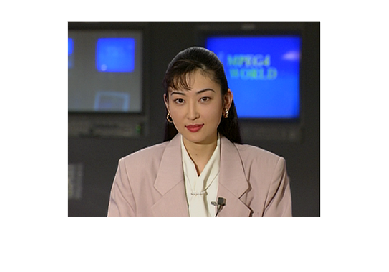

imshow(frames(:, :, :, 1))

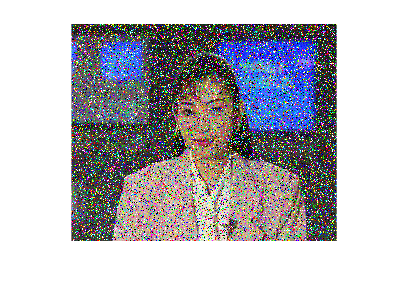

% noise generation
sigma = 20; 
kappa = 5;
mu = 0;
s = 0.3;
groundTruth = frames(:, :, :, 1);
imshow(noisify(groundTruth, sigma, mu, kappa, s));

groundTruth: uint8

function result = noisify(groundTruth, sigma, mu, kappa, s)
    H = size(groundTruth, 1);
    W = size(groundTruth, 2);
    num_channels = size(groundTruth, 3);
    gaussian_noise = normrnd(mu, sigma, H, W, num_channels);
    poisson_noise = poissrnd(kappa, H, W, num_channels);
    
    result = double(groundTruth) + gaussian_noise + poisson_noise;
    
    result(result > 255) = 255;
    result(result < 0) = 0;

    for i=1:H
        for j=1:W
            if rand() < s
                result(i, j, :) = noisy_pixel(num_channels);
            end
        end
    end
    result = result/255;
end

function pixel = noisy_pixel(num_channels)
    pixel = zeros(1, 1, 3);
    for i=1:num_channels
        if rand() < 0.5
            pixel(1, 1, i) = 0;
        else
            pixel(1, 1, i) = 255;
        end
    end
end

